# Correlacion de señales

Obtener o medir la correlacion significa encontrar semejanzas entre dos señales

Ejemplo 1

Creando dos señales de prueba. Es la misma señal con un desplazamiento

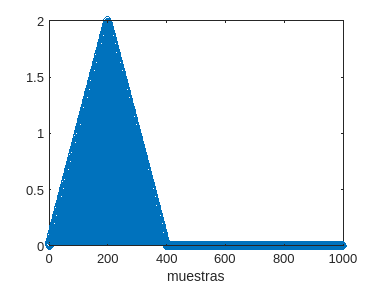

n = 0:999;
xn = zeros(size(n));
xn(1:200) = n(1:200)/100;
xn(201:400) = 2-xn(1:200);

yn1 = circshift(xn,450);

figure()
stem(n,xn)
xlabel("muestras")

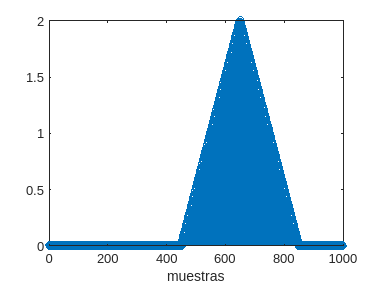

figure()
stem(n,yn1)
xlabel("muestras")

Aplicacion de la correlacion cruzada (xn corr yn1) sobre las señales

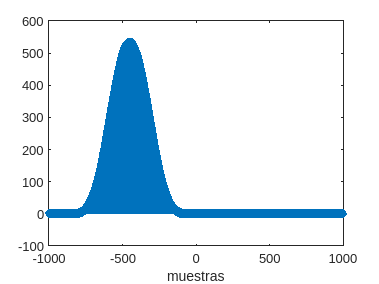

[rxy,lags] = xcorr(xn,yn1);
figure()
stem(lags,rxy)
xlabel("muestras")

Aplicacion de la correlacion cruzada (yn1 corr xn) sobre las señales

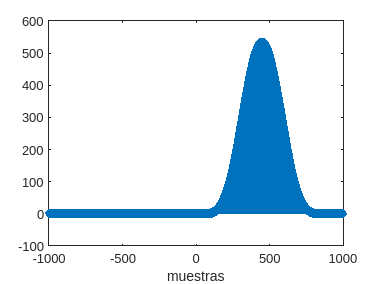

[ryx,lags] = xcorr(yn1,xn);
figure()
stem(lags,ryx)
xlabel("muestras")

Lo anterior demuestra que la correlacion cruzada no es conmutativa

## Normalizacion

Para eliminar los efectos de escala se puede normalizar el calculo de la correlacion cruzada

Recuerde que no es una operacion conmutativa

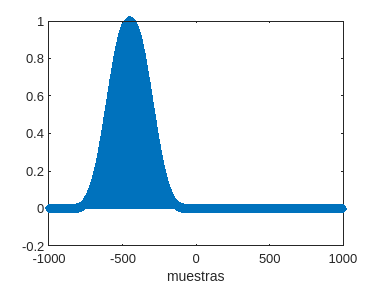

[rxy,lags] = xcorr(xn,yn1,'normalized');
%otras opciones de normalizacion
% 'biased'
% 'unbiased'

figure()
stem(lags,rxy)
xlabel("muestras")

en orden inverso

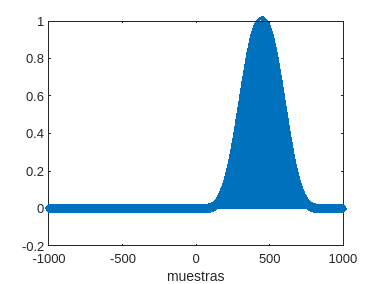

[ryx,lags] = xcorr(yn1,xn,'normalized');
figure()
stem(lags,ryx)
xlabel("muestras")

## Coeficiente de correlacion - matriz de correlacion

Para obtener una medida de la semejanza tambien se puede hacer uso de la matriz de correlacion

Rxx = corrcoef(xn,xn)

Rxx =      1     1
     1     1


Rxy = corrcoef(xn,yn1)

Rxy =     1.0000   -0.4286
   -0.4286    1.0000


El calculo detallado de la matriz de correlacion se muestra a continuacion

Rxy2 = zeros(2);

Rxy2(1,1) = var(xn)/std(xn)^2;
Rxy2(2,2) = var(yn1)/std(yn1)^2;

Rxy2(1,2) = (1/(length(n)-1)) * sum((xn-mean(xn))/std(xn) .* (yn1-mean(yn1))/std(yn1));
Rxy2(2,1) = (1/(length(n)-1)) * sum((yn1-mean(yn1))/std(yn1) .* (xn-mean(xn))/std(xn));

Rxy2

Rxy2 =     1.0000   -0.4286
   -0.4286    1.0000
